## Περίληψη

Ο παρακάτω κώδικας είναι μια προσπάθεια ανακατασκευής του αλγορίθμου *Βag of Features* (ή όπως είναι αλλιώς γνωστός και ως *Bag of Words*) σύμφωνα με τον εκπαιδευτικό κώδικα του [ICCV του 2005](http://people.csail.mit.edu/fergus/iccv2005/bagwords.html). Βασικό μέλημα, είναι η κατηγοριοποίηση των προκείμενων εικόνων σε δυο βασικές ομάδες:

- Πρόσωπα στο προσκήνιο (*Faces*)

- Παρασκήνιο (*Background*)

Για να μπορέσει η κατηγοριοποίηση να είναι αποτελεσματική, είναι απαραίτητος ο σχηματισμός ενός Διαγράμματος Ροής Εργασίας (*Workflow*) που πλαισιώνεται σε εφαρμογές της Μηχανικής Μάθησης, όπου επιτελούνται διεργασίες όπως:

- *Προετοιμασία και προεπεξεργασία των δεδομένων.* Με διαδικασίες όπως ο διαχωρισμός των δεδομένων σε δεδομένα εκπαίδευσης (*training set*) και ελέγχου (*testing set*) και η δημιουργία ετικετών (*labels*), η κανονικοποίηση τιμών, η αλλαγή του μεγέθους εικόνων, ακόμη και η ρύθμιση επιπρόσθετων παραμέτρων όπως η αντίθεση της εικόνας (*contrast adjustment*) και το χωρικό φιλτράρισμα (*spatial filtering*).

- *Εξαγωγή χαρακτηριστικών.* Η αντίληψη των σημείων ενδιαφέροντος σε ένα σύνολο δεδομένων, όπως είναι οι εικόνες, μπορεί να είναι μια εύκολη διαδικασία για τον άνθρωπο αλλά το ίδιο δεν μπορεί να λεχθεί και για τις υπολογιστικές μηχανές. Τα χαρακτηριστικά λοιπόν είναι ένα ξεχωριστό και δεσπόζων είδος πληροφορίας στον τομέα της Υπολογιστικής Όρασης, η συνεισφορά των οποίων αναιρεί τον προηγουμένων αναφερόμενο περιορισμό.

- *Εκπαίδευση μοντέλου.*  Όταν τα δυο προηγούμενα βήματα έχουν ολοκληρωθεί επιτυχώς και σύμφωνα με τις απαιτήσεις της εκάστοτε εφαρμογής, σειρά έχει η εκπαίδευση ενός μοντέλου. Ανάλογα την προσέγγιση του προβλήματος, ένα μοντέλο μπορεί να είναι επιβλεπόμενης ή μη μάθησης, με το πρώτο να απαιτεί την *a priori* δημιουργία ετικετών σε όλο το μήκος του συνόλου δεδομένων (*dataset*), ενώ στο μοντέλο μη επιβλεπόμενης μάθηση, στόχος είναι να βρεθεί το μοτίβο που εμφανίζουν τα δεδομένα, οπότε η χρήση ετικετών είναι αναλώσιμη.

- *Έλεγχος μοντέλου.* Όταν η διαδικασία της εκπαίδευσης ολοκληρωθεί και πραγματοποιηθούν οι προβλέψεις σε νέα δεδομένα (βάσει του εκπαιδευμένου μοντέλου), θα πρέπει να γίνει έλεγχος της αποδοτικότητας καθώς και της ικανότητας γενίκευσης του μοντέλου στα νέα αυτά δεδομένα. Για να γίνει αυτό εισάγονται τα δεδομένα ελέγχου και σχηματίζονται μέθοδοι αξιολόγησης όπως confusion matrices, καμπύλες ROC (*Receiver Operating Characteristic*) ή υπολογισμός της ακρίβειας (*Accuracy*)

## 

*Διάγραμμα Ροής Εργασίας*

## Εφαρμογή

clear;clc;close('all');

% Set a seed for reproducibility of the experiment
s = rng(1);

mkdir Workspace\Codebook

mkdir Workspace\SIFT_features_of_interest_points

mkdir Workspace\Quantized_vector_descriptors

mkdir Workspace\SIFT_features_of_interest_points

% Φόρτωσε τα στοιχεία από το Directory και δημιούργησε το datastore
fileLocation = uigetdir();
Datastore = imageDatastore(fileLocation,"IncludeSubfolders",true,"LabelSource","foldernames");
initialLabels = countEachLabel(Datastore);

## Προεπεξεργασία δεδομένων

Πριν γίνει η μετάβαση στο κομμάτι της εξαγωγής χαρακτηριστικών, εφαρμόζεται ένα ακόμη βήμα στην προεπεξεργασία των δεδομένων που είναι ο εντοπισμός σημείων ενδιαφέροντος. Συγκεκριμένα, ο τελευταίος καθίσταται δυνατός με τον εντοπισμό και την δειγματοληψία των πιο "ισχυρών" ακμών μέσω του αλγορίθμου Canny. Ο αλγόριθμος εφαρμόζεται μέσω της εξατομικευμένης συνάρτησης *Edge_Sampling*. Για λόγους συμβατότητας με το παρών απόκομμα κώδικα, έχουν εφαρμοστεί αλλαγές σε συγκεκριμένα σημεία της συνάρτησης. 

%message = checkimagesizes(Trainds,Testds);fprintf(message)
% Αρχικοποίηση της τιμής κατά την οποία θα γίνει η κλιμάκωση και
% προσδιορισμός του άξονα στο οποίο θα εφαρμοστεί.
XScale = 200;

% Για να μπορέσουμε να εκτελέσουμε τον αλγόριθμο ανίχνευσης σημείων ενδιαφέροντος, θα πρέπει να αλλάξουμε
% τον φάκελο έτσι ώστε να μπορεί να εκτελεστεί ένα συγκεκριμένο εκτελέσιμο αρχείο. Για λόγους ευκολίας, 
% δίνεται η δυνατότητα στο χρήστη να επιλέξει χειροκίνητα το μέρος όπου είναι αποθηκευμένη η συνάρτηση 
% Edge_Sampling.m.

getcurrentDirectory = pwd; 
EdgeSamplingLocation = uigetdir();

if isequal(getcurrentDirectory,EdgeSamplingLocation)

else   
    
    cd(EdgeSamplingLocation);
    
end
tic;

[Gray_resized_datastore,Variables] = Edge_Sampling_VN(Datastore,XScale,"WorkspaceDir", ...
                                                                [getcurrentDirectory,'\Workspace']);

Doing Canny on image region 200 by 303 
Sigma               = 1 
Gaussian tail       = 0.0001 
Max kernel size     = 50 
Upper threshold     = 12 
Lower threshold     = 2 
Min edgel intensity = 60 
Min edge length     = 10 
Image border size   = 2 
 
setting convolution kernel and zeroing images 
Kernel size     = 9 
smoothing the image 
computing x derivatives, y derivatives and norm of gradient 
doing non-maximal supression 
Number of edgels after NMS = 11019 
doing hysteresis 
Number of edgels after Hysteresis = 6452 
doing final edge following 
finished osl_canny_ox 
Doing Canny on image region 200 by 303 
Sigma               = 1 
Gaussian tail       = 0.0001 
Max kernel size     = 50 
Upper threshold     = 12 
Lower threshold     = 2 
Min edgel intensity = 60 
Min edge length     = 10 
Image border size   = 2 
 
setting convolution kernel and zeroing images 
Kernel size     = 9 
smoothing the image 
computing x derivatives, y derivatives and norm of gradient 
doing non-maximal sup


total_time = toc; 
fprintf('\nFinished running interest point operator\n');


Finished running interest point operator



fprintf('Total number of images: %d, mean time per image: %f secs\n', numel(Datastore.Files), ...
                                                                total_time/numel(Datastore.Files));

Total number of images: 200, mean time per image: 0.302790 secs


## Εξαγωγή Χαρακτηριστικών

Έχοντας ορίσει τα σημεία ενδιαφέροντος, όπως αυτά προέκυψαν από την διαδικασία δειγματοληψίας των ακμών από την χρήση της εξατομικευμένης συνάρτησης *Edge_Sampling_VN, *στόχος είναι να εξαχθούν χαρακτηριστικά από αυτά τα σημεία χρησιμοποιώντας τον αλγόριθμο SIFT

reset(Gray_resized_datastore)
tic;
features = cell(1,length(Datastore.Files));

for i = 1:length(Datastore.Files)

    im = read(Gray_resized_datastore);
    [features{i},validPoints{i}] = extractFeatures(im,Variables.interest_points{i},"Method","SIFT");

end

total_time=toc;

cd(getcurrentDirectory)
save('Workspace\SIFT_features_of_interest_points\SIFT_features.mat','features');
save('Workspace\SIFT_features_of_interest_points\validPoints.mat','validPoints');

fprintf('\nFinished running descriptor operator\n');


Finished running descriptor operator



fprintf('Total number of images: %d, mean time per image: %f secs\n', length(Datastore.Files), ...
    total_time/length(Datastore.Files));

Total number of images: 200, mean time per image: 0.005460 secs


## Σχηματισμός του Λεξικού (*Codebook*)

Λόγω του γεγονότος ότι ο υπολογισμός των περιγραφέων που προκύπτουν από τον SIFT γίνεται για όλες τις εικόνες, λαμβάνουμε τους δείκτες των εικόνων έμμεσα μέσω των ονομάτων που έχουν. Η συνάρτηση *getindices *εκτελεί το προαναφερθέν έργο. Έπειτα, κι εφόσον έχουν βρεθεί οι δείκτες, χρησιμοποιούνται ως μέσο ευρετηρίασης στην μεταβλητή κελιών (*cell variable*) *features* ώστε να ληφθούν τα αντίστοιχα χαρακτηριστικά και δημιουργείται ο συνολικός πίνακας χαρακτηριστικών, *descriptors*, με κάθετη συνένωση του κάθε χαρακτηριστικού (*vertical concatenation*).


[Trainds,Testds] = splitEachLabel(Gray_resized_datastore.UnderlyingDatastores{:},0.75,'randomized');


Indices = getindices(Trainds,Testds);
descriptors = [];
for i = 1:length(Indices.Train_Indices)

    descriptors =[descriptors; features{Indices.Train_Indices(i)}];

end

[~,Codebook,~] = kmeans(gpuArray(double(descriptors)),300,"MaxIter",10,"Replicates",10);

Codebookfilepath = fullfile([getcurrentDirectory,'\Workspace\Codebook'],'Codebook.mat'); 
save(Codebookfilepath, 'Codebook');

training_descriptors_vq = zeros(length(Indices.Train_Indices),size(Codebook,1));
testing_descriptors_vq = zeros(length(Indices.Test_Indices),size(Codebook,1));

for i=1:length(Indices.Train_Indices)
        
    fprintf('Currently at training image:%d\n',i);
    
    [~,index] = pdist2(Codebook,double(features{Indices.Train_Indices(i)}),'euclidean','Smallest',1);
    N = histcounts(index, size(Codebook,1));
    
    % Beware! To obtain the final percentages for BoF we need to divide by the number of keypoints 
    % per image!

    training_descriptors_vq(i,:)= N./length(index);
   
end

Currently at training image:1
Currently at training image:2
Currently at training image:3
Currently at training image:4
Currently at training image:5
Currently at training image:6
Currently at training image:7
Currently at training image:8
Currently at training image:9
Currently at training image:10
Currently at training image:11
Currently at training image:12
Currently at training image:13
Currently at training image:14
Currently at training image:15
Currently at training image:16
Currently at training image:17
Currently at training image:18
Currently at training image:19
Currently at training image:20
Currently at training image:21
Currently at training image:22
Currently at training image:23
Currently at training image:24
Currently at training image:25
Currently at training image:26
Currently at training image:27
Currently at training image:28
Currently at training image:29
Currently at training image:30
Currently at training image:31
Currently at training image:32
Currently at trai

for i=1:length(Indices.Test_Indices)
        
    fprintf('Currently at testing image:%d\n',i);
    
    [~,index] = pdist2(Codebook,double(features{Indices.Test_Indices(i)}),'euclidean','Smallest',1);
    N = histcounts(index, size(Codebook,1));
    testing_descriptors_vq(i,:)= N./length(index);
   
end

Currently at testing image:1
Currently at testing image:2
Currently at testing image:3
Currently at testing image:4
Currently at testing image:5
Currently at testing image:6
Currently at testing image:7
Currently at testing image:8
Currently at testing image:9
Currently at testing image:10
Currently at testing image:11
Currently at testing image:12
Currently at testing image:13
Currently at testing image:14
Currently at testing image:15
Currently at testing image:16
Currently at testing image:17
Currently at testing image:18
Currently at testing image:19
Currently at testing image:20
Currently at testing image:21
Currently at testing image:22
Currently at testing image:23
Currently at testing image:24
Currently at testing image:25
Currently at testing image:26
Currently at testing image:27
Currently at testing image:28
Currently at testing image:29
Currently at testing image:30
Currently at testing image:31
Currently at testing image:32
Currently at testing image:33
Currently at testin

TrainingVQDfilepath = fullfile([getcurrentDirectory,'\Workspace\Quantized_vector_descriptors'], ...
                                                                     'training_descriptors_vq.mat');
TestingVQDfilepath = fullfile([getcurrentDirectory,'\Workspace\Quantized_vector_descriptors'], ...
                                                                      'testing_descriptors_vq.mat');

save(TrainingVQDfilepath,'training_descriptors_vq');
save(TestingVQDfilepath,'testing_descriptors_vq');

## Εκπαίδευση Ταξινομητή

Η μέθοδος που επιλέγεται να χρησιμοποιηθεί για την ταξινόμηση των εικόνων είναι επιβλεπόμενης μάθησης. Συγκεκριμένα, για λόγους ευκολίας, χρησιμοποιείται η έτοιμη συνάρτηση [*fitcauto*](https://www.mathworks.com/help/stats/fitcauto.html) η οποία δίνει την δυνατότητα αυτόματης επιλογής του καλύτερου ταξινομητή για το εκάστοτε σύνολο δεδομένων εκπαίδευσης. Στις επιπρόσθετες δυνατότητες που παρέχει, επιλέχθηκε Kfold = 10 και ενεργοποίηση παράλληλης εκτέλεσης κώδικα

|====================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BoxConstraint|  KernelScale | KernelFuncti-| PolynomialOr-|  Standardize |
|      | result |             | runtime     | (observed)  |              |              | on           | der          |              |
|====================================================================================================================================|
|    1 | Best   |     0.37333 |     0.23785 |     0.37333 |      0.33598 |            - |       linear |            - |         true |
|    2 | Accept |     0.37333 |     0.16474 |     0.37333 |         1000 |            - |       linear |            - |        false |
|    3 | Accept |     0.45333 |     0.12172 |     0.37333 |        0.001 |            - |   polynomial |            2 |        false |
|    4 | Best   |     0.35333 |     0.11075 |     0.353

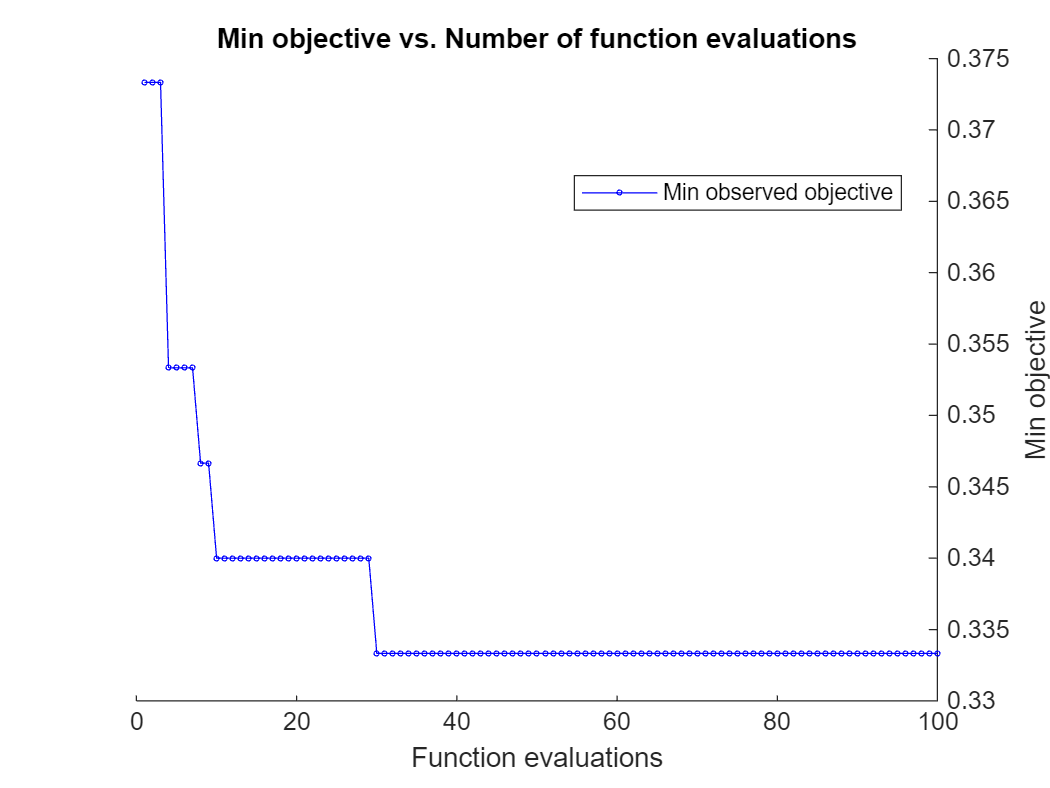

classifier = fitcsvm(training_descriptors_vq,Trainds.Labels, 'OptimizeHyperparameters', ...
    'all','HyperparameterOptimizationOptions', struct('MaxObjectiveEvaluations',100,'Kfold',10,...
    'Optimizer','gridsearch','NumGridDivisions',20));

[predictedLabels, scores]= predict(classifier,testing_descriptors_vq);

## Αξιολόγηση Ταξινομητή

Η τελική αξιολόγηση του ταξινομητή προκύπτει μέσω του υπολογισμού του confusion matrix, όπου το άθροισμα των διαγώνιων στοιχείων του διαιρεμένο με το πλήθος αυτών δίνει τη ακρίβεια του μοντέλου.

confusionMatrix = confusionmat(Testds.Labels,predictedLabels);
Accuracy = sum(diag(confusionMatrix)) / sum(confusionMatrix(:))

Accuracy = 0.7200

## Οπτικοποίηση του Bag of Visual Words για μια εικόνα

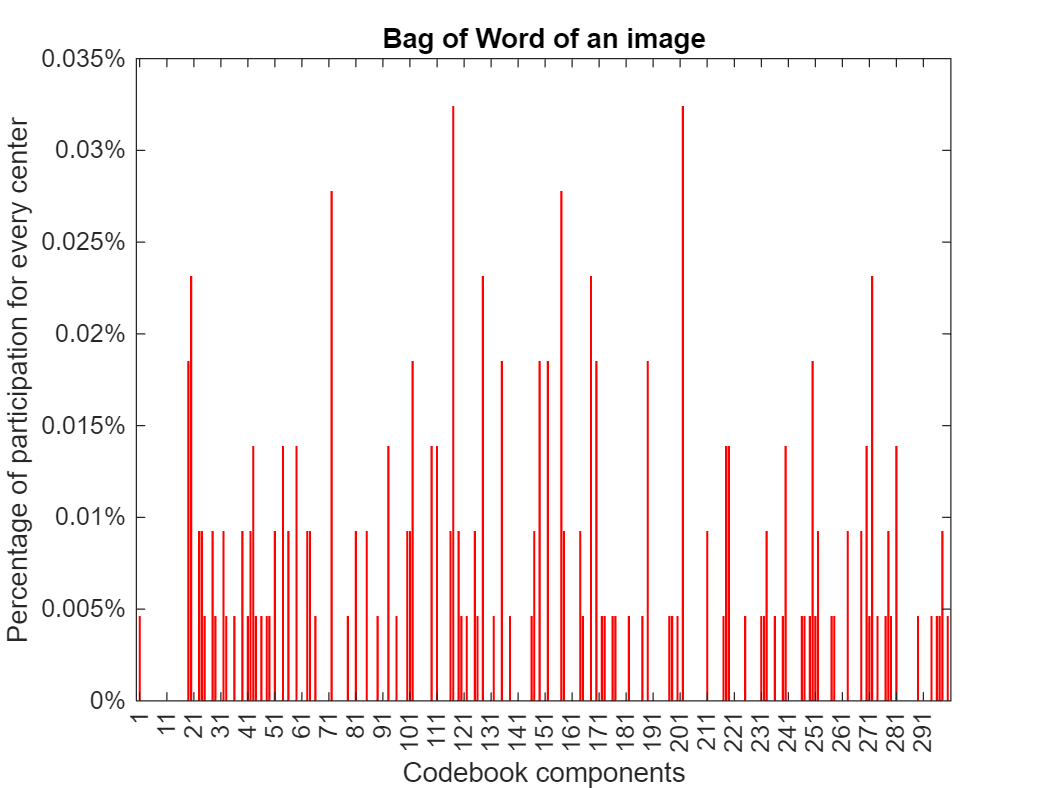

bar(training_descriptors_vq(1,:),'r'); 
xticks(1:10:size(Codebook,1));
xticklabels; 
ytickformat("percentage")
xlabel("Codebook components")
ylabel("Percentage of participation for every center")
title("Bag of Word of an image")

## Copyright (c) 2024, Nick Vasilakis

## All rights reserved.